# `MATISSE`: 1) Overview

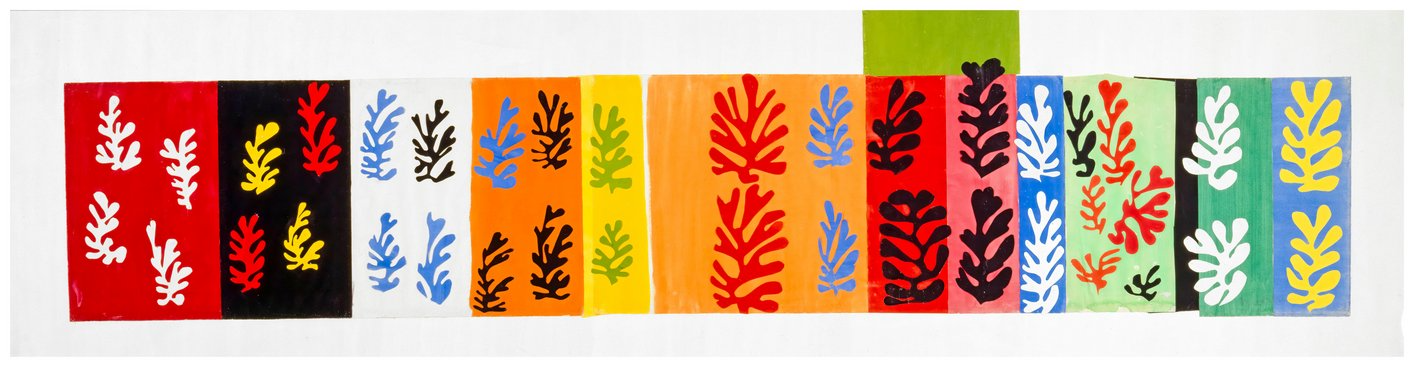

## MATISSE: Overview

*Philip S Rosenberg*

### Design

*"design is a process carried out by people, for people. At its heart is a dialogue between three key people: *[*the designer, the maker and the user*](https://designmuseum.org/exhibitions/designer-maker-user)*." *

MATISSE is a **MA**TLAB **T**oolbox for v**I**tal rate**S** **S**urveillanc**E**. I designed MATISSE to implement the suite of statistical methods that Adalberto Miranda Filho and I describe in [Advances in statistical methods for cancer surveillance research: an age-period-cohort perspective](https://www.frontiersin.org/journals/oncology/articles/10.3389/fonc.2023.1332429/full).

I am responsible for MATISSE's architecture and code - I am the "designer" and the "maker". However, MATISSE does what it does because Adalberto and I have had the priviledge to colloborate with many of the world's top cancer surveillance researchers, its initial "users". 

At this point, MATISSE is ready for its first release to you, the surveilllance research community at large. 

Please try it out and tell us how to improve our software!

MATISSE complements the [Age Period Cohort Analysis Web Tool](https://dceg.cancer.gov/tools/analysis/apc) described [here](https://aacrjournals.org/cebp/article/23/11/2296/14669/A-Web-Tool-for-Age-Period-Cohort-Analysis-of?guestAccessKey=). Indeed, MATISSE recapitulates the web tool together with an ensemble of complementary methods including the [new age-period-cohort model](https://journals.sagepub.com/doi/10.1177/0962280218801121?url_ver=Z39.88-2003&rfr_id=ori:rid:crossref.org&rfr_dat=cr_pub%20%200pubmed), [comparative age-period-cohort analysis](https://link.springer.com/article/10.1186/s12874-023-02039-8), [smoothing methods for Lexis diagrams](https://journals.sagepub.com/doi/10.1177/09622802231192950?url_ver=Z39.88-2003&rfr_id=ori:rid:crossref.org&rfr_dat=cr_pub%20%200pubmed), and [semiparametric age-period-cohort analysis](https://jamanetwork.com/journals/jamanetworkopen/fullarticle/2819747).

MATISSE puts graphics first, numbers second. That is reflected in its name. 

MATISSE is freely available. You can use it at no cost via [MATLAB Online](https://www.mathworks.com/products/matlab-online.html). If you have access to a licensed copy of MATLAB, you may prefer to run MATISSE on your local machine.   

Why MATLAB? Why not [R](https://www.r-project.org)? The honest answer is I became proficient in MATLAB long before the [R Project](https://www.r-project.org/about.html) got under way. To this day, MATLAB remains the world's best software for the matrix calculations that underpin MATISSE's algorithms. We do hope to implement our methods in R or Python. But MATISSE is available **now**. 

Fundamentally, MATISSE is an [object oriented system](https://www.mathworks.com/company/technical-articles/introduction-to-object-oriented-programming-in-matlab.html). MATISSE produces 'objects' that you manipulate using object-specific 'methods'. This concept will be very familiar to R users. Different types of data are represented as objects, for example, `rates` objects encapsulate age-specific event rates over time. Models are also represented as objects. for example, `apc` objects encapsulate an age-period-cohort analysis. 

Objects allow you to analyze your data using simple commands. 

All MATLAB Toolboxes, including MATISSE, run within the MATLAB environment, which works a lot like R. The online version of MATLAB can be accessed through any web browser. 

We will rely on MATLAB's `mlx` or [MATLAB Live Code file format.](https://www.mathworks.com/help/releases/R2025b/matlab/matlab_prog/live-script-file-format.html?searchHighlight=mlx+file&s_tid=doc_srchtitle) Live scripts are interactive documents that combine code, outputs and annotations. Our user's guide consists of a set of `mlx` files. Live scripts promote reproducible science. We also recommend that you use the MATLAB command line as a 'scratch pad' - a place where you can ask questions and try things out before promoting a piece of code to your `mlx` files.

Yes, you will need to learn some MATLAB to use MATISSE. We designed our users guide to help flatten your learning curve. 

### Users guide

The core MATISSE users guide is a collection of eight `mlx` files each associated with a corresponding PowerPoint file. Taken together, the PowerPoint files present a survey course based on our paper. We expect to add to this core collection over time.

***If you see it in the course, you can do it in MATISSE.***

We recommend that you:

- Work through the `mlx` files with the corresponding course notes at hand. 

- Locate each function on the MATISSE system map (see below). 

### System map

- Conceptually, you can think of MATISSE as a network. That network has a map, shown here:

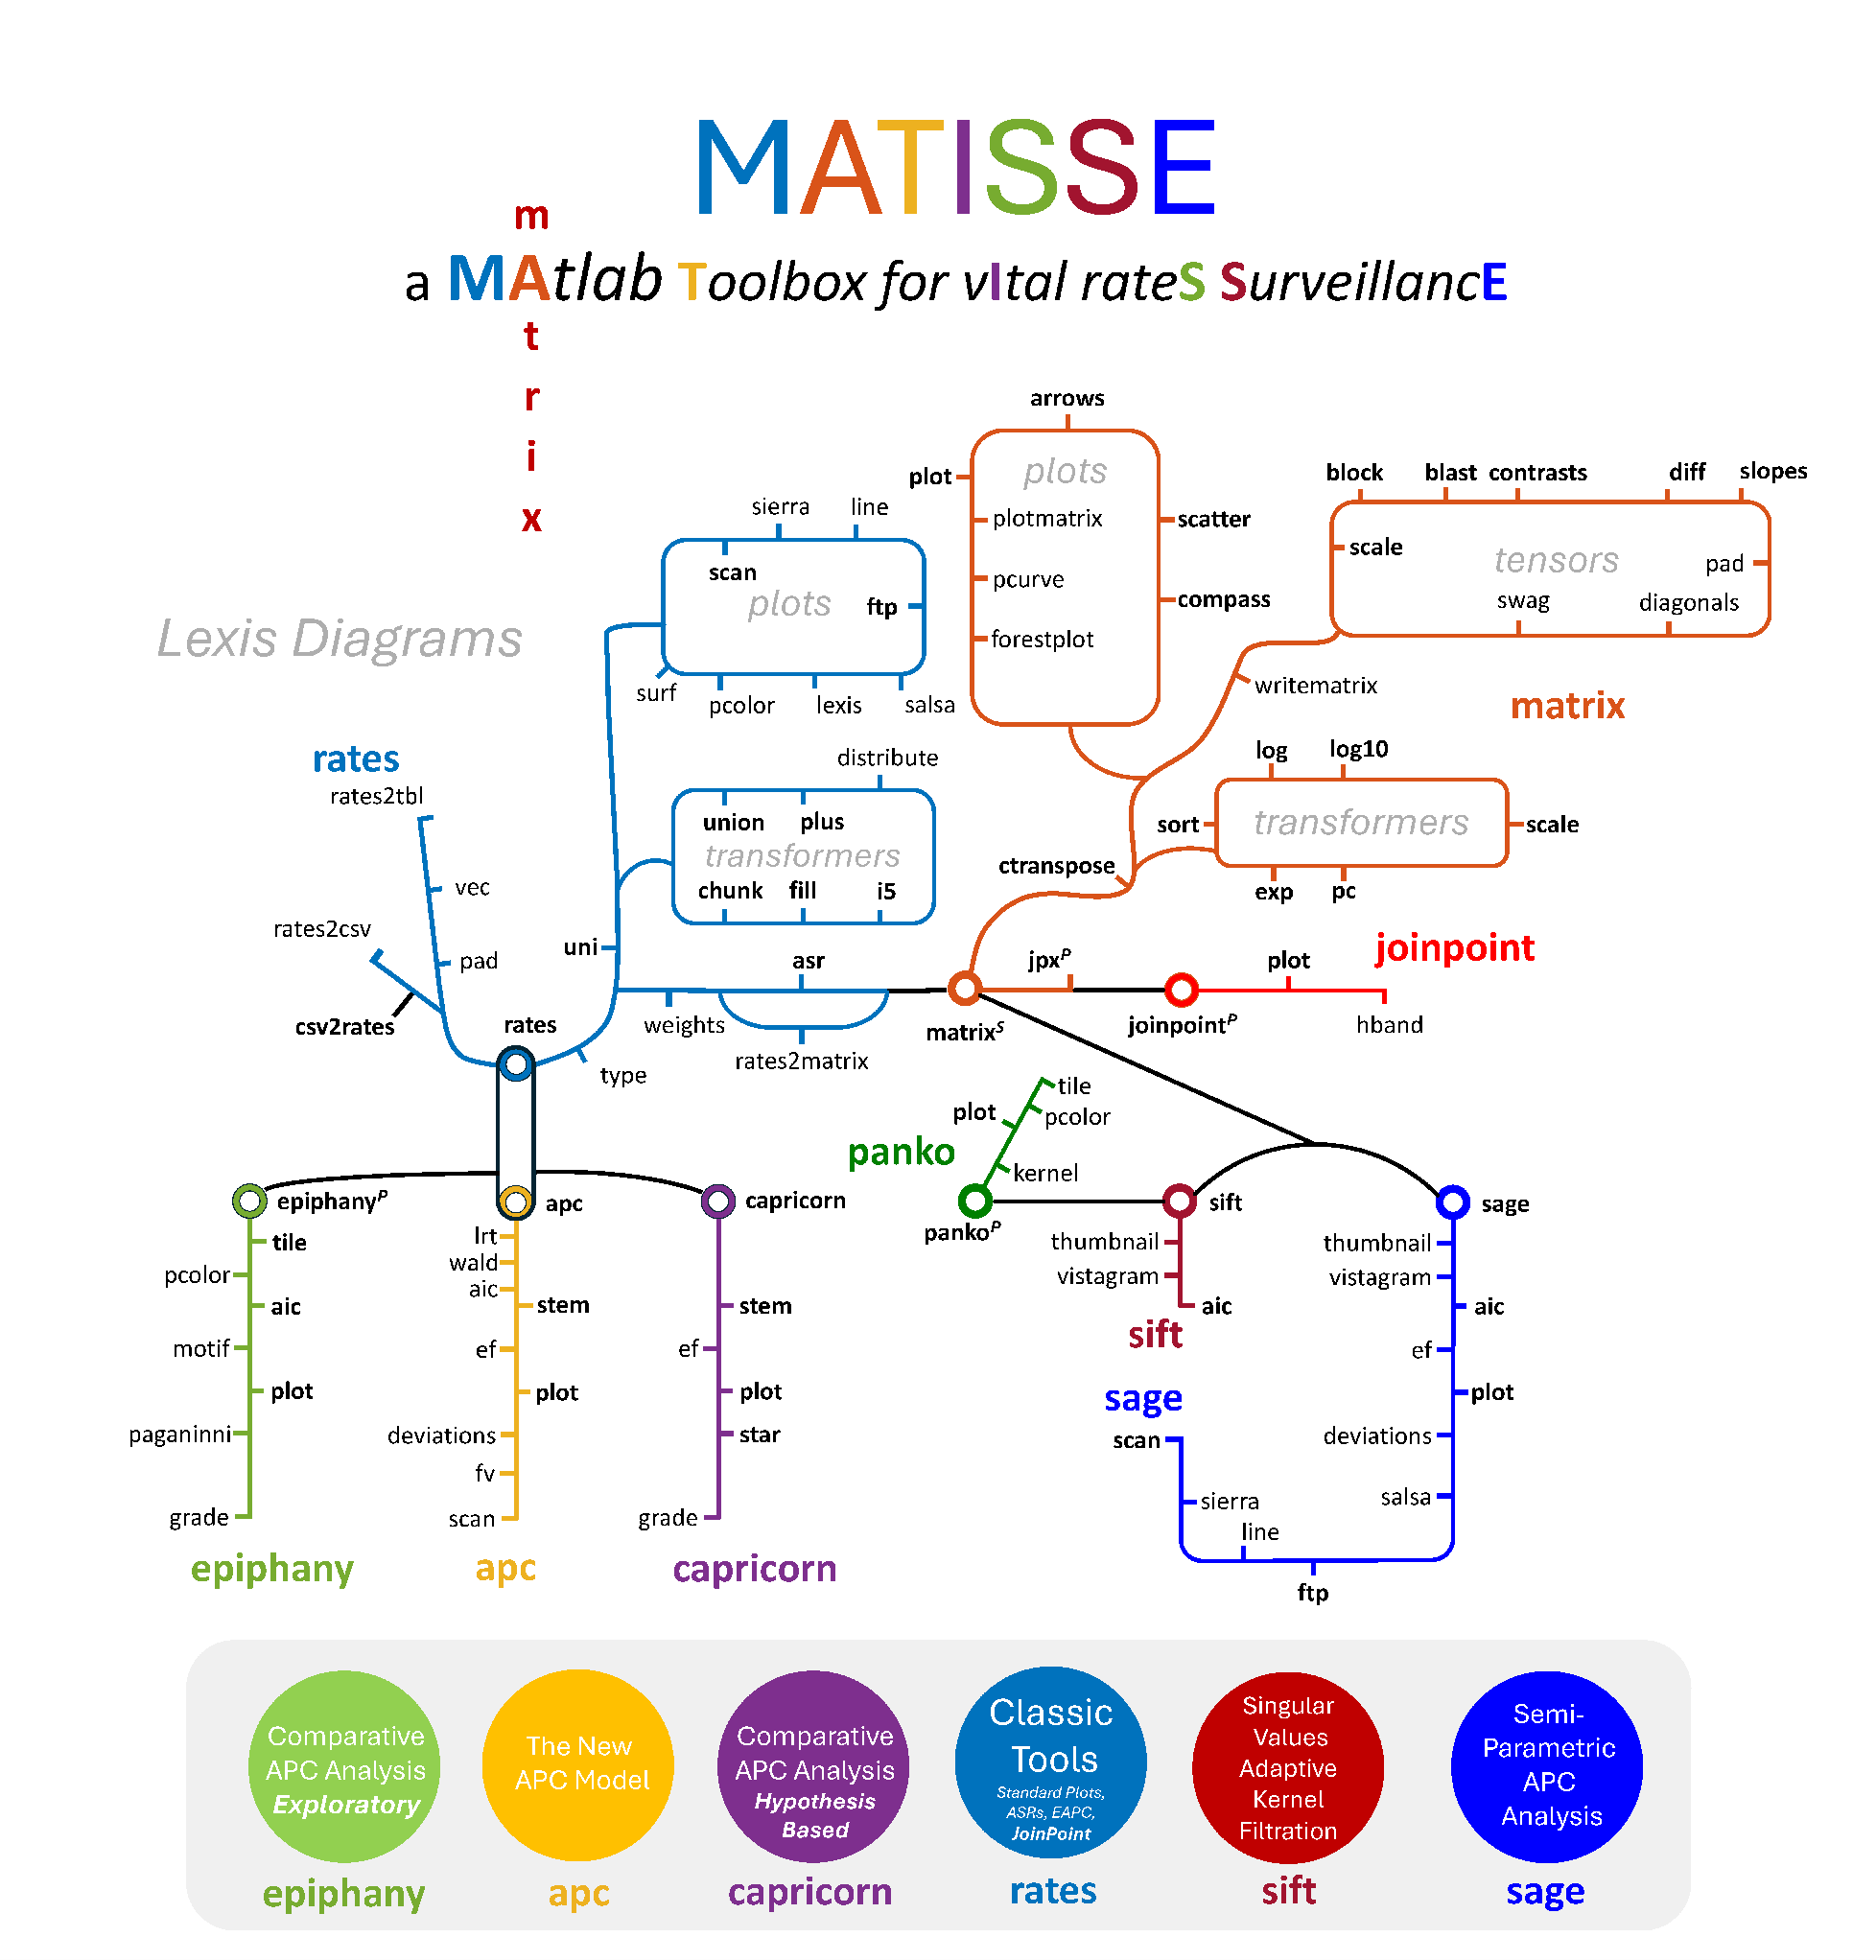

matisse('map')

- Think of MATISSE as a transportation system that takes your from your data to information to knowledge. 

- The system diagram above was inspired by the London Tube Map. 

- The major data and model classes are like the train lines, each with its own destination and purpose. 

- The stops along the way are the class-specific methods.

- There are several key hubs where you can transit from one data type or model to another.

- Many stops have the same name, for example, there are six `plot` methods. What each one does is appropriate for it's class. 

- To review a particular class method, you can issue MATLAB commands of the form  `>> help class/method`

## Example data 

MATISSE includes 16 built-in Lexis diagrams. Go ahead - make a selection!

Example = 6; % all example data are stored as 1x1

DELTA = 2;   % you can chunk the 1x1 data to 2x2 or 5x5 

 

r = ratesdata(Example); % use the ratesdata function to grab one or more examples

switching to data directory . . .
                   . . . and back


switch DELTA
    case 1
        R0 = r;
    case 2
        R0 = chunk(r, 'AgeBlock', 2, 'PerBlock', 2);
    case 5
        R0 = chunk(r, 'AgeBlock', 5, 'PerBlock', 5);
end


*Add a small value to any zero cells using the *`rates/fill`* method  . . .*

R = fill(R0);
disp(R)

F colon NHW
 
  *   25 age groups 35 - 36 through 83 - 84.
  *   13 calendar periods 1993 - 1994 through 2017 - 2018.
  *   37 nominal birth cohorts 1910 through 1982.
 
  #   events:  min 17.0   mean 286.7   max 793.0   
 
93172 total events in 160240341 PY.


## Help

- ***Help is always at your fingertips.*** 

- Every MATISSE function has detailed help. At the MATLAB command line >> simply type `help `followed by the name of an object, method, or function. Help information is hot-linked.

For example:

help rates/rates

  rates Event rates ascertained over a Lexis diagram.
 
  * You must include 'Events' and 'Offset' data.
 
  * You can characterize the underlying Lexis diagram using
    'ages' and 'periods' or 'lexis' property-value pairs.
 
  R = rates(...
            'Events', <AxP numeric matrix>, ...
            'Offset', <AxP numeric matrix>, ...
            'fullname', 'string', ...
            'label', 'string', ...
            'chromacode', 'string', ...
            'event_label', 'string', ...
            'offset_units', 'string', ...
            'offset_tick', <scalar>, ...
            'ages', <A+1 cutpoints [a0, a1, ..., aA]>, ...
            'periods', <P+1 cutpoints [p0, p1, ..., pP>, ...
            'lexis', <[a0, p0, DELTAa, DELTAp]>)
 
  See also uni, pcolor.

    Documentation for rates/rates



You can see a list of class methods using the `methods` function (scroll left and right):

methods rates


Methods for class rates:

asr           chunk         disp          distribute    end           fill          ftp           geode         geometry      i5            isempty       lexis         line          pad           pcolor        plus          poissrnd      randn         rates         rates2csv     rates2matrix  rates2tbl     salsa         scan          sierra        size          subsasgn      subsref       surf          type          uni           union         vec           weights       



Alternatively,  you can view help in a stand-alone window using the `doc` function, as in `doc('rates')`. Try that out from the command line.

## **Graphics**

MATISSE aims to provide you with graphic outputs that are highly informative yet require no additional coding. For that reason, many stylistic options need to be set by default. 

At some point, you may wish to tweak the appearance of a graph. 

You have two options:

- You can export your outputs and use another package, such as R or [Origin](https://www.originlab.com). 

- You can interact with [MATLAB's 'handle graphics' system](https://www.mathworks.com/help/matlab/creating_plots/graphics-objects.html). In brief, every line or patch or piece of text in a MATLAB graph is an object with numerous properties.

MATISSE helps you access MATLAB graphics using it's `go` values and the `ego` function. **These serve as a bridge** between you and MATLAB's graphics.

MATISSE also includes 30+ graphics functions that do not appear on the system map. Some are general purpose methods, others assist class methods. At some point you may wish to use them.

Type `help MATISSE/graphics` at the command line to see a list, or `help graphics/<method>` to learn about a particular function. 

In the next section, we will illustrate how this works using the r`ates` object you selected above.

### `go` values and the `ego` function

Here is a heat map of your rates data produced using default graphics options. 

You may wish to manage your window sizes using the MATLAB [`figure`](https://www.mathworks.com/help/releases/R2025b/matlab/ref/figure.html?searchHighlight=figure&s_tid=doc_srchtitle) command.

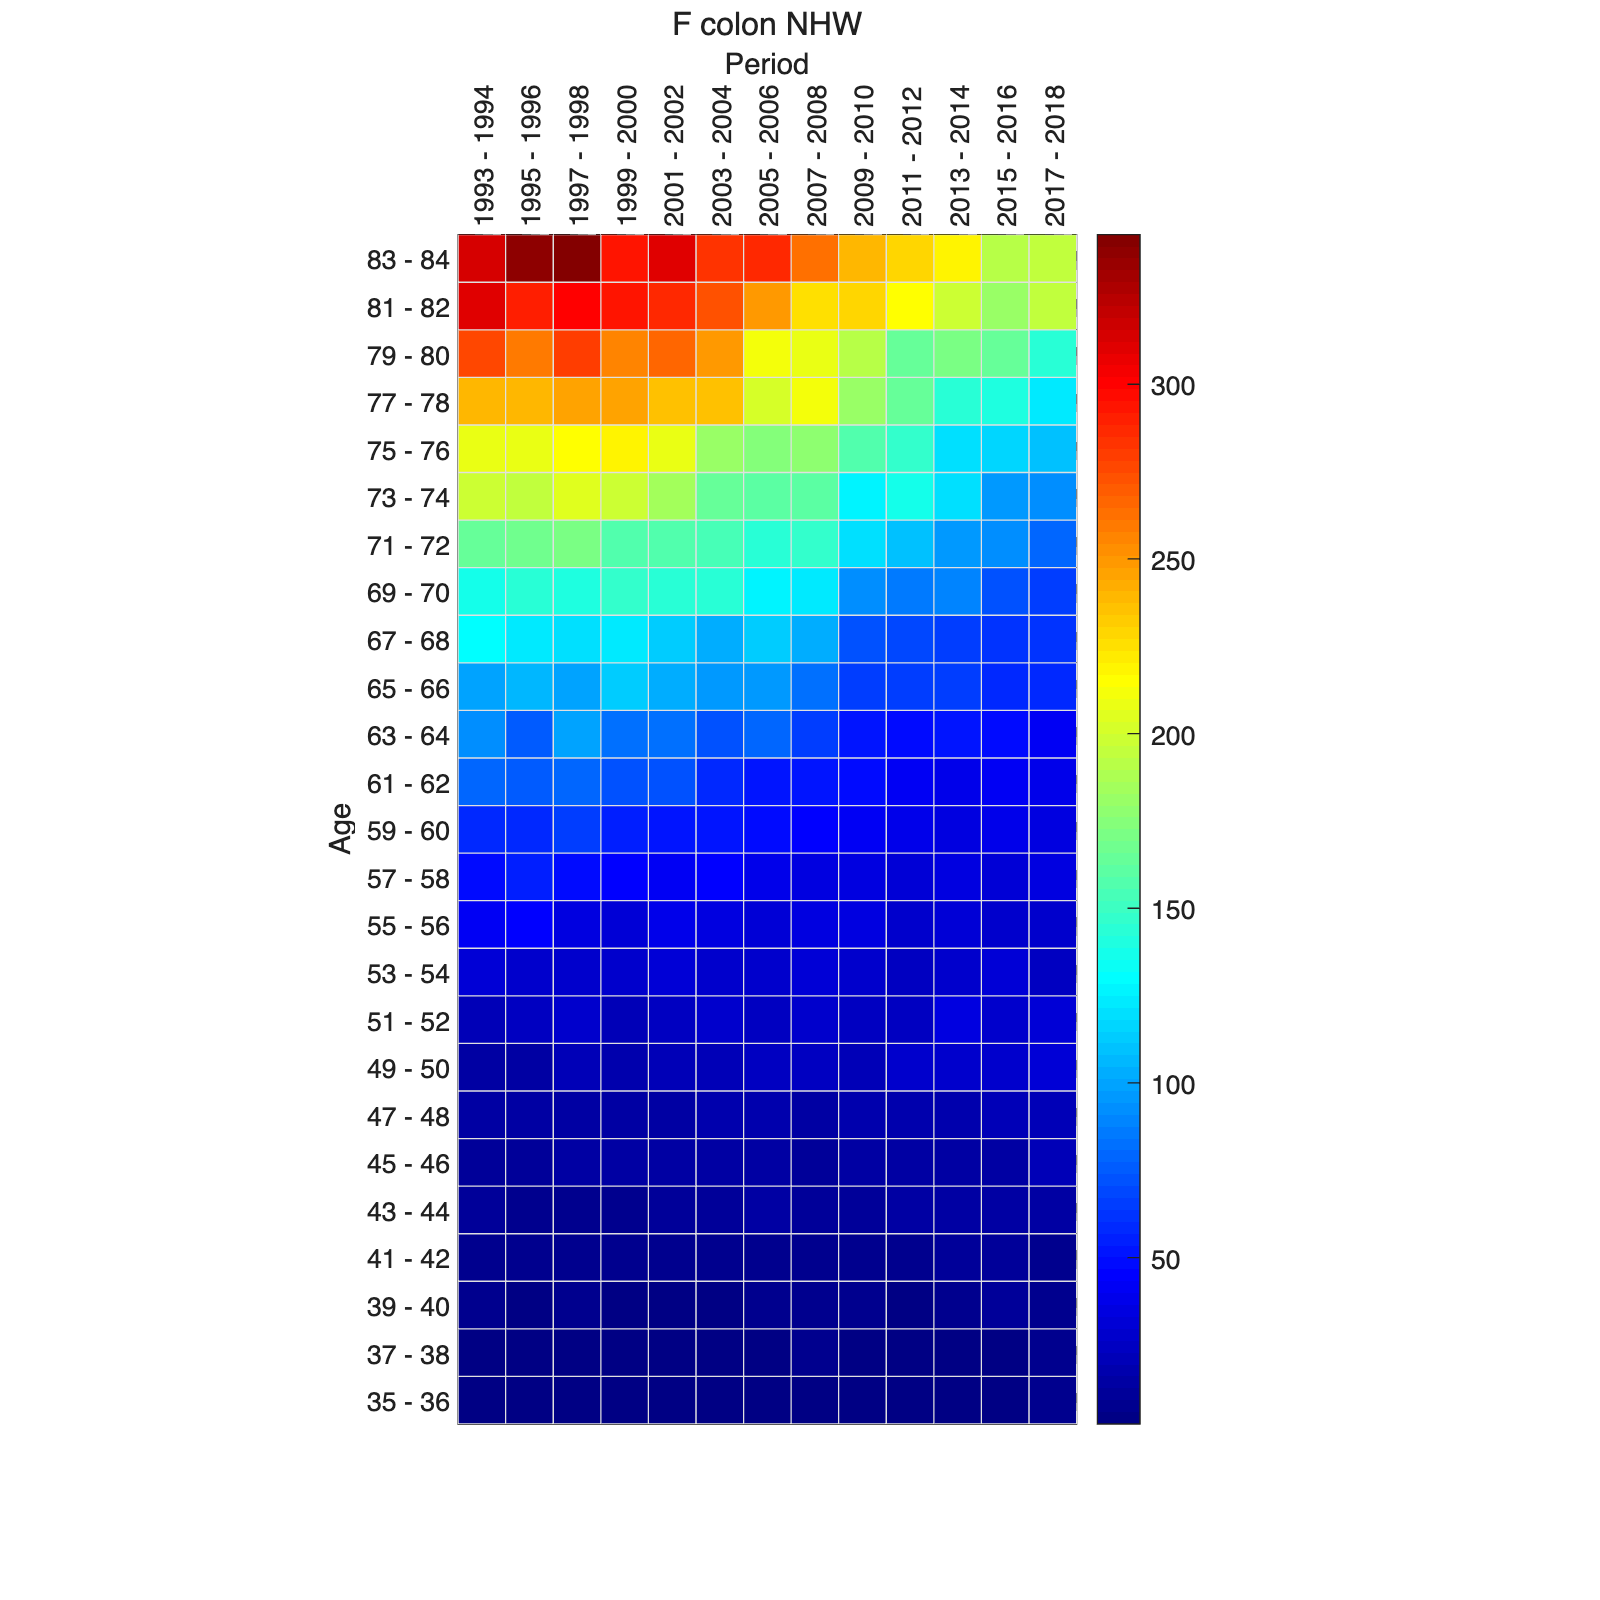

figure('Position', [0 0 800 800])
pcolor(R) % the pcolor function produces heat maps

In MATISSE you specify MATLAB **g**raphics **o**ptions using the `go` function, which produces a structure array of MATLAB property-value pairs (scroll up and down).

help go 

  go Set graphics options for MATISSE functions.
 
  PVP = go(<property-value pairs>)
 
  * Some options apply to all functions, others to particular functions.
 
  Property-Value Pairs:
 
  'Width'       - width of the x-axis relative to the y-axis (default 1.2672)
  'CI'          - values of 1 (true) or 0 (false)
  'Trim'        - number of edge values to trim (default 0)
  'XLim'        - [Lo Hi], x-axis limits
  'YLim'        - [Lo Hi], y-axis limits
  'Legend'      - values of 1 (true) or 0 (false, default)
 
  'LineWidth'   - scalar or vector, default 1
  'LineColor'   - scalar or vector of clarinet colors 1 - 54 (default 1)
  'LineStyle'   - values between 1 (default) and 5 corresponding to:
                       '-', '--', ':', '-.', 'none'
  'Marker'      - values between 1 (default) and 16 corresonding to:
                      'o', 'square', '^', 'diamond', '.',       ( 1 - 5 )
                      'v', '>', '<', 'pentagram', 'hexagram',  

You can alter the appearance of a MATISSE-based plot by changing one or more `go` value and then passing the desired `go` values to a graphics function. Every graphics function has its own defaults. You can start from a copy of those defaults using the `ego` function. That is often the easiest way.

help ego

  ego dEfault Graphics Options for MATISSE functions.
 
  PVP = ego('class', <'class name'>, 'method', <'method name'>)
 
  Supported classes and functions:
 
     'rates'
     'apc'
     'joinpoint'
     'panko'
     'sift'
     'sage'
     'capricorn'
     'epiphany'
     'tbl'
     'matrix'
     'survival'
     'comprisk'
     'graphics' (the collection of functions in MATISSE/graphics)
 
     'categoric'
 
  See also go.



Let's change the appearance of our heat map.

Start with the standard graphics options, and specify some changes. For example:

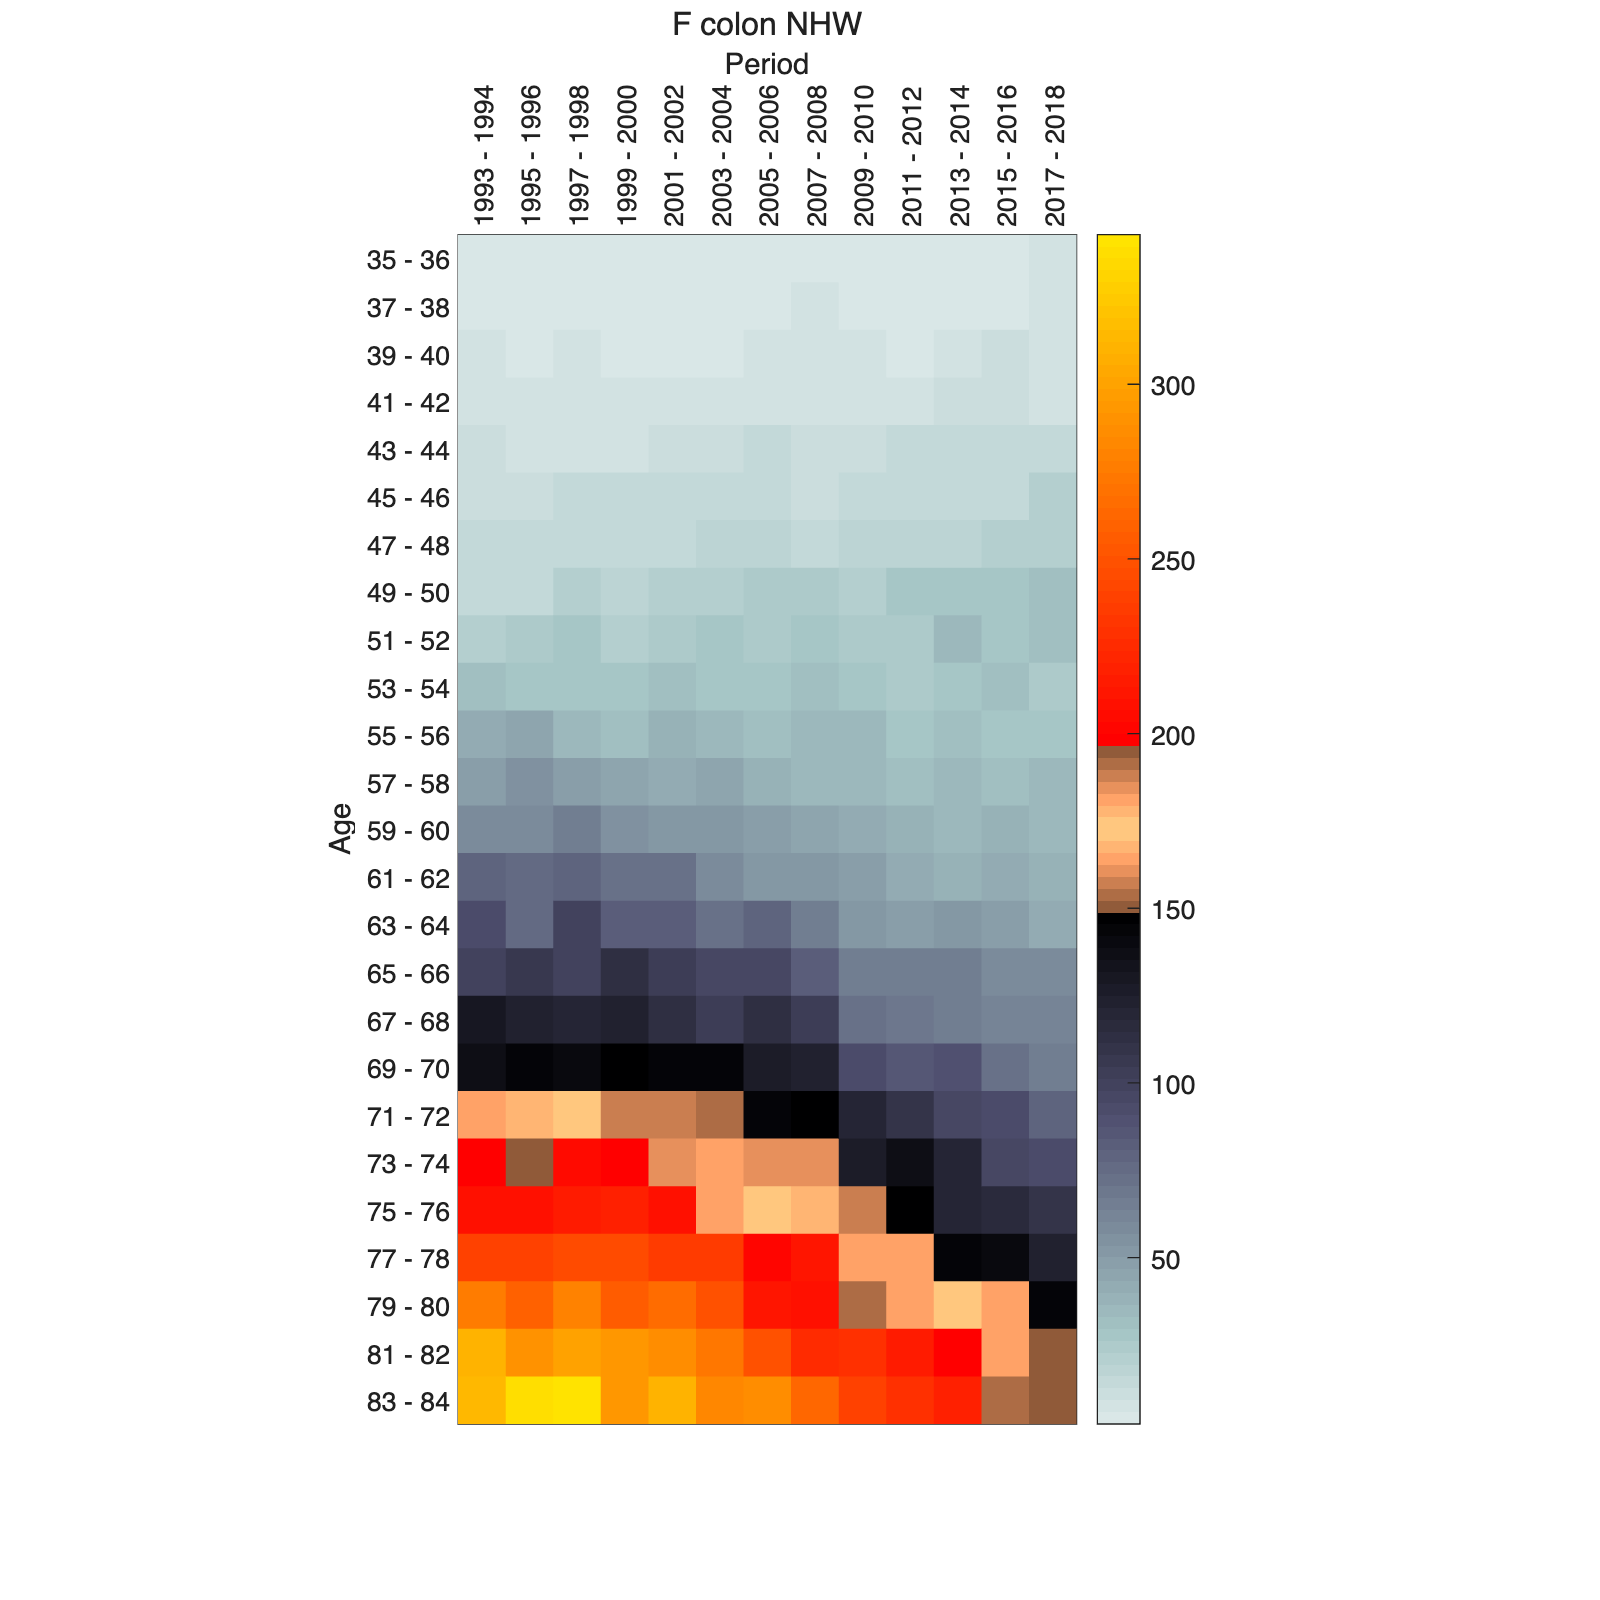

pvp0 = ego('class', 'rates', 'method', 'pcolor');
pvp0.colormap = 'nepal';
pvp0.YDir = 'normal';
pvp0.Grid = 0;

figure('Position', [0 0 800 800])
pcolor(R, pvp0)

### The `clarinet` function - MATISSE's standard palette of line colors

MATISSE includes a custom color map with 54 standard colors that MATISSE uses to specify line colors. You refer to each color's corresponding rgb triple using integers from 1 (light blue), 2 (orange), ..., through 54 (dark grey).

help clarinet

  clarinet A colormap selected from 54 standard colors.
 
  MAP = clarinet(nColors)
 
  or
 
  MAP = clarinet('nColors', <value>, 'startColor', <value>)
 
  or
 
  MAP = clarinet('colors', <values>)
 
  MAP is a matrix of RGB triples.
 
  Property-Value Pairs:
 
  'nColors'    - integer <= 54 (default 54)
  'startColor' - integer from 1 through 54 (default 1)
 
  or
 
  'colors'     - vector of integers with values from 1 through 54
 
  colors:
 
  1  light blue
  2  orange
  3  gold
  4  purple
  5  green
  6  opal
  7  brick
  8  blue
  9  red
  10 forest green
  11 magenta
  12 black
  13 powder blue
  14 khaki
  15 silver
  16 orange
  17 yellow
  18 teal
  19 turquoise
  20 purple
  21 brown
  22 tomato
  23 golden rod
  24 khaki
  25 olive
  26 sea green
  27 dark slate grey
  28 dark turquoise
  29 steel blue
  30 navy
  31 blue violet
  32 dark slate blue
  33 dark orchid
  34 fuchsia
  35 pink
  36 wheat
  37 

Let's take a look: The code to make the next graph is relegated to a local function named `helper1` located at the bottom of this file.

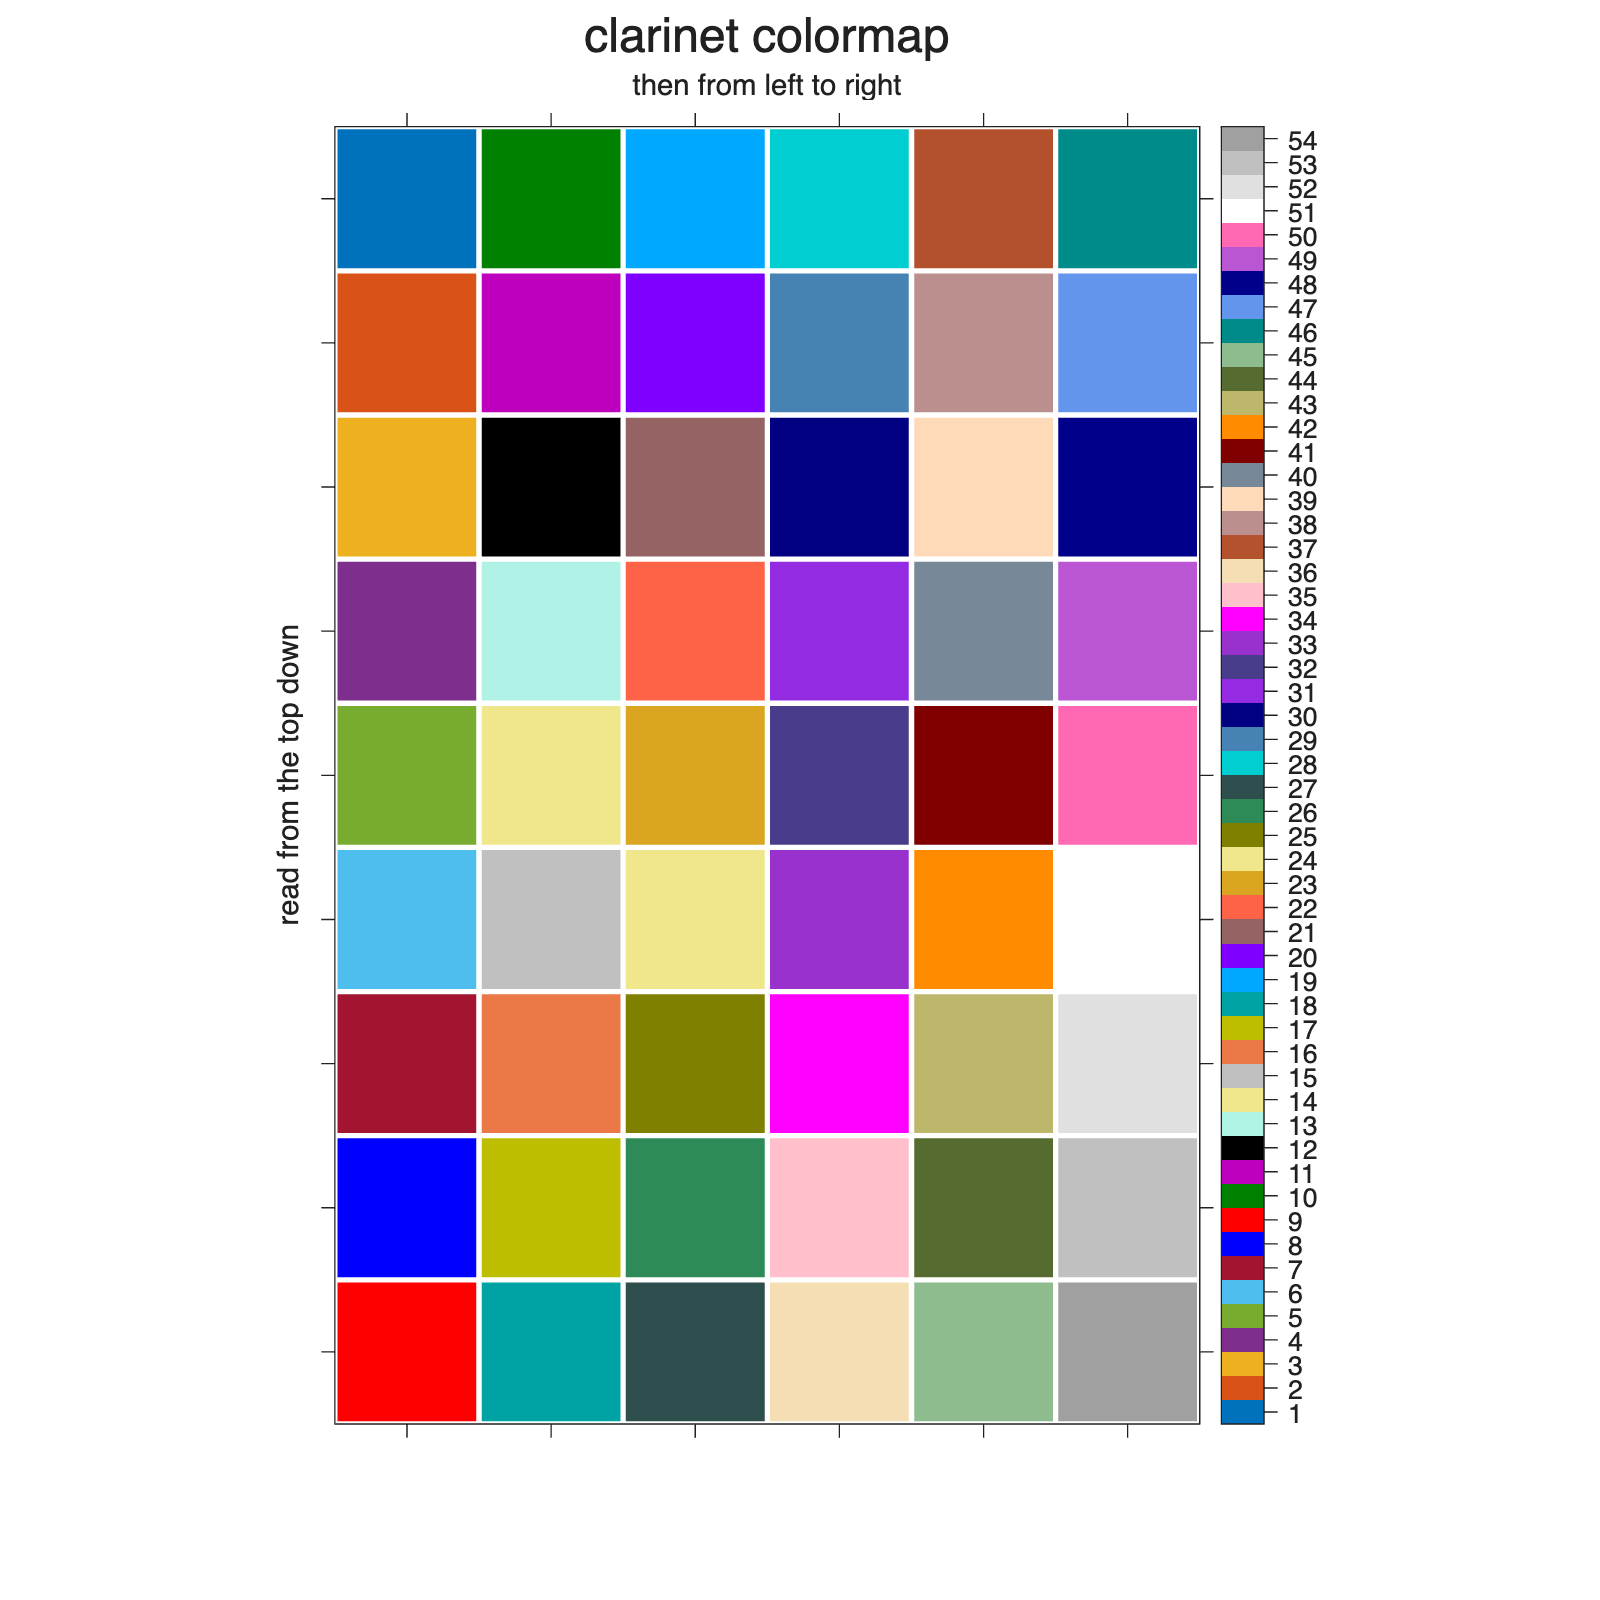

F2 = figure('Position', [0 0 800 800]);
helper1(F2) 

### `africa` and `nepal` - two additional MATISSE color maps

- `africa` - green-black-red color map 

- `nepal `- bone-copper-autumn color map

You can also choose any built-in MATLAB [colormap](https://www.mathworks.com/help/releases/R2025b/matlab/ref/colormap.html?searchHighlight=colormap&s_tid=doc_srchtitle). 

## `tbl` objects - a lightweight container for tabular data

A `tbl` object contains a matrix of numbers with corresponding row and column labels. tbl objects and methods in MATISSE are somewhat analogous to `data.frame` or `matrix` classes in R. There is nothing about `tbl` objects that is specific to vital rates. For that reason, this important class was omitted from MATISSE's system map. Even so, `tbl` objects are ubiquitous. Please don't confuse MATISSE's lightweight `tbl` objects with MATLAB's much more versatile [`table`](https://www.mathworks.com/help/releases/R2025b/matlab/ref/table.html?searchHighlight=table&s_tid=doc_srchtitle) objects!

You already picked an example `rates` object above. Let's extract a `tbl` of rates using the `rates/type` method, and then print out some values.

T = type(R, 'comp', 'r'); 
disp(T([1 end], [1 end]))

F colon NHW
Age by Period    1993 - 1994   2017 - 2018
35 - 36               2.3553        7.2225
83 - 84                312.3        193.32
 


## `matrix` objects - MATISSE's secret sauce

MATLAB uses the term 'matrix' to describe any scalar, vector or 2D array of numbers, regardless of its underlying [numeric type](https://www.mathworks.com/help/releases/R2025b/matlab/numeric-types.html). 

In contrast, in MATISSE, a `matrix` object contains a random vector or matrix stored as a `tbl` object, along with it's variance-covariance matrix. As far as we know, the `matrix` schema is unique to MATISSE. It simplifies many statistical calculations that otherwise would require lengthy blocks of repetitive code. 

As shown on the system map, `matrix` methods include three collections: *transformers*, *plots*, and *tensors*. 

Tensors include powerful multi-linear operators including  `block` and  `blast` (matrix sums and averages, respectively, within blocked rows and columns). Transformers and tensors automatically calculate variances and covariances: That is one of the most powerful capabilities built into MATISSE's architecture.

## Scripting

The best way to start coding is to copy all or part of an `mlx` file that includes analyses and workflows that you wish to perform on your own data. Then edit the template code to match the specifics of your data and fine-tune the outputs to suit your needs.

The `mlx` files in this users guide are a good place to start.

We have some firm opinions about good coding practices. We will share these later on. 

## local function

`tile `display of the `clarinet` color map

function helper1(F)

figure(F)

I = tbl(...
    'data', reshape(1:54, 9, 6), ...
    'fullname', 'clarinet colormap', ...
    'labels', {'read from the top down', 'then from left to right'});

tile(I, ...
    go(...
    'colormap', 'clarinet', ...
    'Grid', 1, 'GridColor', 51, 'GridWidth', 2, ...
    'colorbar', 'eastoutside', ...
    'labels', [1 1 1], 'FontSize', [10 10 18]))

end